# 腿部五连杆机构运动学/动力学分析

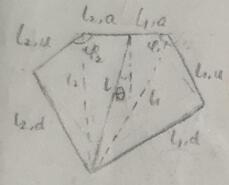

syms l theta
syms phi_1 phi_2
syms l_1_a l_1_u l_1_d
syms l_2_a l_2_u l_2_d

## 1 逆运动学 


$$(\varphi_1,\varphi_2)=f(l,\theta)$$


$l_1=\sqrt{l_{1,a}^2+l^2+2l_{1,a}lsin\theta}$    (1)

$l_2=\sqrt{l_{2,a}^2+l^2-2l_{2,a}lsin\theta}$    (2)

$\varphi_1=acos\frac{l_1^2+l_{1,a}^2-l^2}{2l_1l_{1,a}}+acos\frac{l_1^2+l_{1,u}^2-l_{1,d}^2}{2l_1l_{1,u}}$    (3)

$\varphi_2=acos\frac{l_2^2+l_{2,a}^2-l^2}{2l_2l_{2,a}}+acos\frac{l_2^2+l_{2,u}^2-l_{2,d}^2}{2l_2l_{2,u}}$    (4)

l_1 = sqrt(l_1_a^2+l^2+2*l_1_a*l*sin(theta));
l_2 = sqrt(l_2_a^2+l^2-2*l_2_a*l*sin(theta));
phi_1_sym = acos((l_1^2+l_1_a^2-l^2)/(2*l_1*l_1_a)) ...
           +acos((l_1^2+l_1_u^2-l_1_d^2)/(2*l_1*l_1_u));
phi_2_sym = acos((l_2^2+l_2_a^2-l^2)/(2*l_2*l_2_a)) ...
           +acos((l_2^2+l_2_u^2-l_2_d^2)/(2*l_2*l_2_u));

## 2 正运动学


$$(l,\theta_l)=f^{-1}(\varphi_1,\varphi_2)$$


$(l_{1,a}-l_{1,u}cos\varphi_1+lsin\theta)^2+(l_{1,u}sin\varphi_1-lcos\theta)^2=l_{1,d}^2$    (5)

$(l_{2,a}-l_{2,u}cos\varphi_2-lsin\theta)^2+(l_{2,u}sin\varphi_2-lcos\theta)^2=l_{2,d}^2$    (6)

令 $x_e = lsin\theta$ , $y_e=lcos\theta$，记 $x_i=l_{i,a}-l_{i,u}cos\varphi_i$ ,  $y_i = l_{i,u}sin\varphi_i$ , $i=1,2$

方程组 (5)(6) 改写为

$(x_e+x_1)^2+(y_e-y_1)^2=l_{1,d}^2$    (7)

$(x_e-x_2)^2+(y_e-y_2)^2=l_{2,d}^2$    (8)

syms x_e y_e x_1 y_1 x_2 y_2
eq1 = (x_e+x_1)^2+(y_e-y_1)^2-l_1_d^2;
eq2 = (x_e-x_2)^2+(y_e-y_2)^2-l_2_d^2;
[x_e_sol,y_e_sol] = solve(eq1,eq2,x_e,y_e);
x_e_sym = simplify(x_e_sol(1));
y_e_sym = simplify(y_e_sol(1));

求解结果


$$x_e=
\frac{y_{1}\sigma_1-y_{2}\sigma_1+{l_{1,d}}^2\,x_{1}+{l_{1,d}}^2\,x_{2}-{l_{2,d}}^2\,x_{1}-{l_{2,d}}^2\,x_{2}+x_{1}\,{x_{2}}^2-{x_{1}}^2\,x_{2}-x_{1}\,{y_{1}}^2-x_{1}\,{y_{2}}^2+x_{2}\,{y_{1}}^2+x_{2}\,{y_{2}}^2-{x_{1}}^3+{x_{2}}^3+2\,x_{1}\,y_{1}\,y_{2}-2\,x_{2}\,y_{1}\,y_{2}}{2\,\left({x_{1}}^2+2\,x_{1}\,x_{2}+{x_{2}}^2+{y_{1}}^2-2\,y_{1}\,y_{2}+{y_{2}}^2\right)}$$



$$y_e=
\frac{x_{1}\sigma_1+x_{2}\sigma_1-{l_{1,d}}^2\,y_{1}+{l_{1,d}}^2\,y_{2}+{l_{2,d}}^2\,y_{1}-{l_{2,d}}^2\,y_{2}+{x_{1}}^2\,y_{1}+{x_{1}}^2\,y_{2}+{x_{2}}^2\,y_{1}+{x_{2}}^2\,y_{2}-y_{1}\,{y_{2}}^2-{y_{1}}^2\,y_{2}+{y_{1}}^3+{y_{2}}^3+2\,x_{1}\,x_{2}\,y_{1}+2\,x_{1}\,x_{2}\,y_{2}}{2\,\left({x_{1}}^2+2\,x_{1}\,x_{2}+{x_{2}}^2+{y_{1}}^2-2\,y_{1}\,y_{2}+{y_{2}}^2\right)}$$


其中


$$\sigma_1=
\sqrt{-{\left(-{l_{1,d} }^2 -2\,l_{1,d} \,l_{2,d} -{l_{2,d} }^2 +{x_1 }^2 +2\,x_1 \,x_2 +{x_2 }^2 +{y_1 }^2 -2\,y_1 \,y_2 +{y_2 }^2 \right)}\,{\left(-{l_{1,d} }^2 +2\,l_{1,d} \,l_{2,d} -{l_{2,d} }^2 +{x_1 }^2 +2\,x_1 \,x_2 +{x_2 }^2 +{y_1 }^2 -2\,y_1 \,y_2 +{y_2 }^2 \right)}}$$


## 3 雅可比矩阵

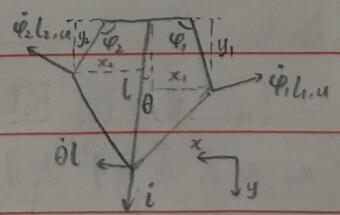

直接对式 (3)(4) 或方程组 (5)(6) 的解求偏导的结果非常复杂，而根据速度关系可以得到表达式相对简单的雅可比矩阵，即

$\dot{q}=J^{-1}\dot{p}$    (9)

其中，$q=\left[\matrix{
\varphi_1 & \varphi_2
}\right]^T$，$p=\left[\matrix{
l & \theta
}\right]^T$

令 $x_e = lsin\theta$ , $y_e=lcos\theta$，记 $x_i=l_{i,a}-l_{i,u}cos\varphi_i$ ,  $y_i = l_{i,u}sin\varphi_i$ , $i=1,2$

速度约束方程

$\left(\dot\varphi_1l_{1,u}\left[\matrix{-sin\varphi_1 \cr cos\varphi_1}\right]\right)^T\left[\matrix{x_e+x_1 \cr y_e-y_1}\right]
=
\left(\dot l\left[\matrix{sin\theta \cr cos\theta}\right]+\dot\theta l\left[\matrix{cos\theta \cr -sin\theta}\right]\right)^T\left[\matrix{x_e+x_1 \cr y_e-y_1}\right]$    (10)

$\left(\dot\varphi_2l_{2,u}\left[\matrix{sin\varphi_2 \cr cos\varphi_2}\right]\right)^T\left[\matrix{x_e-x_2 \cr y_e-y_2}\right]
=
\left(\dot l\left[\matrix{sin\theta \cr cos\theta}\right]+\dot\theta l\left[\matrix{cos\theta \cr -sin\theta}\right]\right)^T\left[\matrix{x_e-x_2 \cr y_e-y_2}\right]$    (11)

由式 (10)(11) 可得

$\frac{\partial\varphi_1}{\partial l}=
\frac{1}{l_{1,u}}\frac{(x_e+x_1)sin\theta+(y_e-y_1)cos\theta}{-(x_e+x_1)sin\varphi_1+(y_e-y_1)cos\varphi_1}$    (12)

$\frac{\partial\varphi_1}{\partial\theta}=
\frac{l}{l_{1,u}}\frac{(x_e+x_1)cos\theta-(y_e-y_1)sin\theta}{-(x_e+x_1)sin\varphi_1+(y_e-y_1)cos\varphi_1}$    (13)

$\frac{\partial\varphi_2}{\partial l}=
\frac{1}{l_{2,u}}\frac{(x_e-x_2)sin\theta+(y_e-y_2)cos\theta}{(x_e-x_2)sin\varphi_2+(y_e-y_2)cos\varphi_2}$    (14)

$\frac{\partial\varphi_2}{\partial\theta}=
\frac{l}{l_{2,u}}\frac{(x_e-x_2)cos\theta-(y_e-y_2)sin\theta}{(x_e-x_2)sin\varphi_2+(y_e-y_2)cos\varphi_2}$    (15)

$J=\left[\matrix{
\frac{\partial\varphi_1}{\partial l} & \frac{\partial\varphi_1}{\partial\theta} \cr \frac{\partial\varphi_2}{\partial l} & \frac{\partial\varphi_2}{\partial\theta}
}\right]^{-1}$    (16)

legPphi1Pl = @(l,theta,phi,xe,ye,xi,yi,li_u)1/li_u(1) ...
                *((xe+xi(1))*sin(theta)+(ye-yi(1))*cos(theta)) ...
                /(-(xe+xi(1))*sin(phi(1))+(ye-yi(1))*cos(phi(1)));
legPphi1Ptheta = @(l,theta,phi,xe,ye,xi,yi,li_u)l/li_u(1) ...
                *((xe+xi(1))*cos(theta)-(ye-yi(1))*sin(theta)) ...
                /(-(xe+xi(1))*sin(phi(1))+(ye-yi(1))*cos(phi(1)));
legPphi2Pl = @(l,theta,phi,xe,ye,xi,yi,li_u)1/li_u(2) ...
                *((xe-xi(2))*sin(theta)+(ye-yi(2))*cos(theta)) ...
                /((xe-xi(2))*sin(phi(2))+(ye-yi(2))*cos(phi(2)));
legPphi2Ptheta = @(l,theta,phi,xe,ye,xi,yi,li_u)l/li_u(2) ...
                *((xe-xi(2))*cos(theta)-(ye-yi(2))*sin(theta)) ...
                /((xe-xi(2))*sin(phi(2))+(ye-yi(2))*cos(phi(2)));
legJacob = @(l,theta,phi,xe,ye,xi,yi,li_u)inv([ ...
                legPphi1Pl(l,theta,phi,xe,ye,xi,yi,li_u), ...
                legPphi1Ptheta(l,theta,phi,xe,ye,xi,yi,li_u); ...
                legPphi2Pl(l,theta,phi,xe,ye,xi,yi,li_u), ...
                legPphi2Ptheta(l,theta,phi,xe,ye,xi,yi,li_u)]);

## 4 (动态)静力学

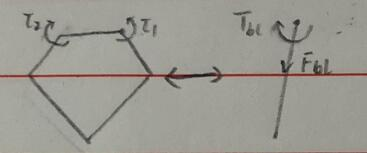

记 $\gamma=\left[\matrix{F_{bl} & T_{bl}}\right]^T$，$\tau=\left[\matrix{\tau_1 & \tau_2}\right]^T$

根据虚功原理可得

$\tau=J^T\gamma$    (17)

## 5 动力学参数

$\theta_l=\theta+\theta_b$    (18)

$m_l=\sum{m_{i,p}} \ (i=1,2\ p=u,d)$    (19)

通过插值拟合得到腿部质心位置和惯量关于 $l,\theta$ 的近似函数

$(l_w,l_b)=f_{l,c}(l,\theta)$    （20）

$I_l=f_{l,I}(l,\theta)$    (21)

## 附录1 运动学验证

% % leg parameters (test)
% test_param = struct( ...
%   "l_1_a", 1, ...
%   "l_1_u", 3, ...
%   "l_1_d", 5, ...
%   "l_2_a", 1, ...
%   "l_2_u", 3, ...
%   "l_2_d", 5);
% % kinematic function
% legIkine = matlabFunction(subs([phi_1_sym;phi_2_sym], ...
%               {l_1_a,l_1_u,l_1_d,l_2_a,l_2_u,l_2_d}, ...
%               {test_param.l_1_a,test_param.l_1_u,test_param.l_1_d, ...
%                test_param.l_2_a,test_param.l_2_u,test_param.l_2_d}));
% legXi = @(phi)[test_param.l_1_a-test_param.l_1_u*cos(phi(1))
%                test_param.l_2_a-test_param.l_2_u*cos(phi(2))];
% legYi = @(phi)[test_param.l_1_u*sin(phi(1))
%                test_param.l_2_u*sin(phi(2))];
% legXe = matlabFunction(subs(x_e_sym,{l_1_d,l_2_d}, ...
%           {test_param.l_1_d,test_param.l_2_d}));
% legYe = matlabFunction(subs(y_e_sym,{l_1_d,l_2_d}, ...
%           {test_param.l_1_d,test_param.l_2_d}));
% legFkine = @(xe,ye)[sqrt(xe^2+ye^2);atan2(xe,ye)];
% % reference trajectory
% dt = 2*pi/32;
% t = 0:dt:2*pi;
% xe_ref_t = sin(t);
% ye_ref_t = 4+cos(t);
% l_ref_t = sqrt(xe_ref_t.^2+ye_ref_t.^2);
% theta_ref_t = atan2(xe_ref_t,ye_ref_t);
% % feedback trajectory
% phi_t = zeros(2,size(t,2));
% xi_t = zeros(2,size(t,2));
% yi_t = zeros(2,size(t,2));
% xe_t = zeros(1,size(t,2));
% ye_t = zeros(1,size(t,2));
% l_t = zeros(1,size(t,2));
% theta_t = zeros(1,size(t,2));
% for i = 1:size(t,2)
%   phi_t(:,i) = legIkine(l_ref_t(i),theta_ref_t(i));
%   xi_t(:,i) = legXi(phi_t(:,i));
%   yi_t(:,i) = legYi(phi_t(:,i));
%   xe_t(i) = legXe(xi_t(1,i),xi_t(2,i),yi_t(1,i),yi_t(2,i));
%   ye_t(i) = legYe(xi_t(1,i),xi_t(2,i),yi_t(1,i),yi_t(2,i));
%   l_t(i) = sqrt(xe_t(i)^2+ye_t(i)^2);
%   theta_t(i) = atan2(xe_t(i),ye_t(i));
% end
% % speed
% l_D1_ref_t = (l_ref_t(2:end)-l_ref_t(1:end-1))/dt;
% l_D1_ref_t = [l_D1_ref_t(1),l_D1_ref_t];
% theta_D1_ref_t = (theta_ref_t(2:end)-theta_ref_t(1:end-1))/dt;
% theta_D1_ref_t = [theta_D1_ref_t(1),theta_D1_ref_t];
% phi_D1_t = (phi_t(:,2:end)-phi_t(:,1:end-1))/dt;
% phi_D1_t = [phi_D1_t(:,1),phi_D1_t];
% phi_D1_ref_t = zeros(2,size(t,2));
% l_D1_t = zeros(1,size(t,2));
% theta_D1_t = zeros(1,size(t,2));
% for i = 1:size(t,2)
%   J = legJacob(l_t(i),theta_t(i),phi_t(:,i),xe_t(i),ye_t(i), ...
%                xi_t(:,i),yi_t(:,i),[test_param.l_1_u;test_param.l_2_u]);
%   phi_D1_ref_t(:,i) = J\[l_D1_ref_t(i);theta_D1_ref_t(i)];
%   p = J*phi_D1_t(:,i);
%   l_D1_t(i) = p(1);
%   theta_D1_t(i) = p(2);
% end
% % plot
% figure;
% subplot(4,2,1); hold on; grid on;
% plot(t,xe_ref_t,"lineWidth",1);
% plot(t,xe_t,".","lineWidth",1);
% legend("ref","fdb"); xlabel("t"); title("x_e");
% subplot(4,2,2); hold on; grid on;
% plot(t,ye_ref_t,"lineWidth",1);
% plot(t,ye_t,".","lineWidth",1);
% legend("ref","fdb"); xlabel("t"); title("y_e");
% subplot(4,2,3); hold on; grid on;
% plot(t,l_ref_t,"lineWidth",1);
% plot(t,l_t,".","lineWidth",1);
% legend("ref","fdb"); xlabel("t"); title("l");
% subplot(4,2,4); hold on; grid on;
% plot(t,theta_ref_t,"lineWidth",1);
% plot(t,theta_t,".","lineWidth",1);
% legend("ref","fdb"); xlabel("t"); title("\theta");
% subplot(4,2,5); hold on; grid on;
% plot(t,l_D1_ref_t(:),"lineWidth",1);
% plot(t,l_D1_t(1,:),".","lineWidth",1);
% legend("ref","fdb"); xlabel("t"); title("l_d");
% subplot(4,2,6); hold on; grid on;
% plot(t,theta_D1_ref_t(:),"lineWidth",1);
% plot(t,theta_D1_t(:),".","lineWidth",1);
% legend("ref","fdb"); xlabel("t"); title("\theta_d");
% set(gcf,"position",[0,0,600,600]);
% subplot(4,2,7); hold on; grid on;
% plot(t,phi_D1_ref_t(1,:),"lineWidth",1);
% plot(t,phi_D1_t(1,:),".","lineWidth",1);
% legend("ref","fdb"); xlabel("t"); title("\phi_1_d");
% subplot(4,2,8); hold on; grid on;
% plot(t,phi_D1_ref_t(2,:),"lineWidth",1);
% plot(t,phi_D1_t(2,:),".","lineWidth",1);
% legend("ref","fdb"); xlabel("t"); title("\phi_2_d");